clc
clear

LEFT = 0;
RIGHT = 1;
TOP = 2;
BOTTOM = 3;
CORNER_LT = 4;
CORNER_RT = 5;
CORNER_LB = 6;
CORNER_RB = 7;
NOT_BOUNDARY = 8;

FREE = 0;
CONST_U = 1;
CONST_UX = 2;
CONST_UY = 3;
CONST_F = 4;
CONST_FX = 5;
CONST_FY = 6;

## Shape

% % Circle
% r = 2;
% th = linspace(0,2*pi,1e2+1);
% x_shape = r * cos(th);
% y_shape = r * sin(th);

% % Beam
H_beam = 10;
L_beam = 1;
x_shape = [0,0,L_beam,L_beam,0];
y_shape = [0,-H_beam,-H_beam,0,0];

## Boundaries

% x_bound{1} = [0,L_beam];
% y_bound{1} = [0,0];
% boundType{1} = CONST_UX;
% boundCond{1} = [+1.0,-1.0,+0.0,+0.0];
% 
% x_bound{2} = [0,L_beam];
% y_bound{2} = [-H_beam,-H_beam];
% boundType{2} = CONST_U;
% boundCond{2} = [+0.0,+0.0,+0.0,+0.0];

x_bound{1} = [0,0];
y_bound{1} = [0,-.05];
boundType{1} = CONST_UX;
boundCond{1} = [+1.0,-1.0,+0.0,+0.0];

x_bound{4} = [L_beam,L_beam];
y_bound{4} = [0,-.05];
boundType{4} = CONST_UX;
boundCond{4} = [+1.0,-1.0,+0.0,+0.0];

x_bound{2} = [0,0];
y_bound{2} = [-H_beam,-H_beam + .05];
boundType{2} = CONST_U;
boundCond{2} = [+0.0,+0.0,+0.0,+0.0];

x_bound{3} = [L_beam,L_beam];
y_bound{3} = [-H_beam,-H_beam + .05];
boundType{3} = CONST_U;
boundCond{3} = [+0.0,+0.0,+0.0,+0.0];

bGroup = size(x_bound,2);

## Bounding Box

xmin = min(x_shape);
xmax = max(x_shape);
ymin = min(y_shape);
ymax = max(y_shape);

## Grid Sizing

% nx = 50;
% ny = 50;
% Dx = (xmax-xmin)/(nx-1);
% Dy = (ymax-ymin)/(ny-1);

Dx = 0.1;
Dy = 0.05;
nx = (xmax-xmin)/Dx + 1;
ny = (ymax-ymin)/Dy + 1;

## Mesh

[X,Y] = meshgrid( ...
    xmin:Dx:xmax, ...
    ymin:Dy:ymax);
X=reshape(X,[],1);
Y=reshape(Y,[],1);

## Sort In/Out Points

[in,on]=inpolygon(X,Y,x_shape,y_shape);
Xpoints = X(in); Ypoints = Y(in);
Xin=X(in&~on); Yin=Y(in&~on);
Xon=X(on); Yon=Y(on);
Xout=X(~in); Yout=Y(~in);
n = length(Xpoints);

lCount = 1;
rCount = 1;
tCount = 1;
bCount = 1;
cCount = 1;
for j = 1:length(Xon)
    if (ismembertol(Xon(j) + Dx,Xin) && ...
            ismembertol(Yon(j) + Dy,Yon) && ...
            ismembertol(Yon(j) - Dy,Yon))
        Xleft(lCount) = Xon(j); %#ok
        Yleft(lCount) = Yon(j); %#ok
        lCount = lCount + 1;
        continue;
    end

    if (ismembertol(Xon(j) - Dx,Xin) && ...
            ismembertol(Yon(j) + Dy,Yon) && ...
            ismembertol(Yon(j) - Dy,Yon))
        Xright(rCount) = Xon(j); %#ok
        Yright(rCount) = Yon(j); %#ok
        rCount = rCount + 1;
        continue
    end

    if (ismembertol(Yon(j) - Dy,Yin) && ...
            ismembertol(Xon(j) + Dx,Xon) && ...
            ismembertol(Xon(j) - Dx,Xon))
        Xtop(tCount) = Xon(j); %#ok
        Ytop(tCount) = Yon(j); %#ok
        tCount = tCount + 1;
        continue
    end

    if (ismembertol(Yon(j) + Dy,Yin) && ...
            ismembertol(Xon(j) + Dx,Xon) && ...
            ismembertol(Xon(j) - Dx,Xon))
        Xbot(bCount) = Xon(j); %#ok
        Ybot(bCount) = Yon(j); %#ok
        bCount = bCount + 1;
        continue
    end

    if ((ismembertol(Xon(j) + Dx, Xon) && ...
            ismembertol(Yon(j) - Dy, Yon)) || ...
            ((ismembertol(Xon(j) - Dx, Xon) && ...
            ismembertol(Yon(j) - Dy, Yon))) || ...
            (ismembertol(Xon(j) + Dx, Xon) && ...
            ismembertol(Yon(j) + Dy, Yon)) || ...
            ((ismembertol(Xon(j) - Dx, Xon) && ...
            ismembertol(Yon(j) + Dy, Yon))))
        Xcorn(cCount) = Xon(j); %#ok
        Ycorn(cCount) = Yon(j); %#ok
        cCount = cCount + 1;
    end
end

## Sort Boundary Points

for count = 1:bGroup
    [in_bound,on_bound]=inpolygon(X,Y, ...
        x_bound{count},y_bound{count});
    Xbound{count} = X(in_bound)'; %#ok
    Ybound{count} = Y(in_bound)'; %#ok
end

## Plotting

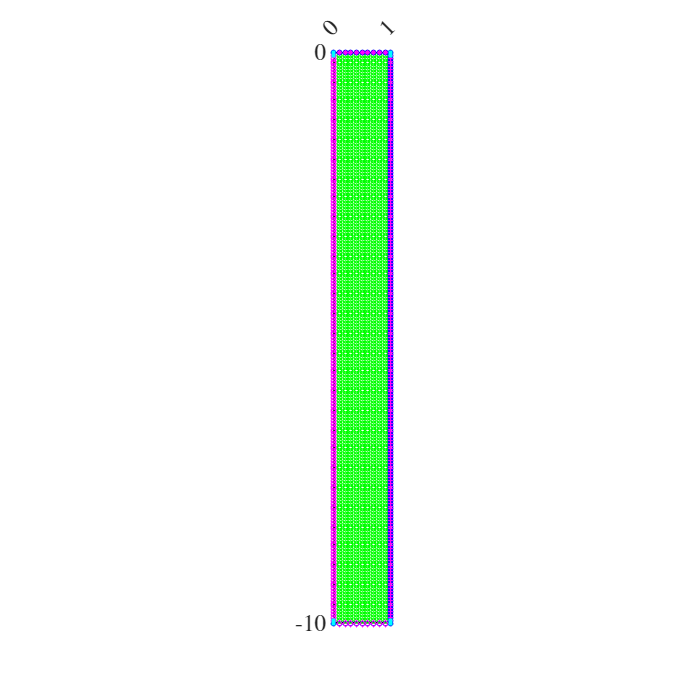

figure("Position",[0,0,400,400]);
set(gca,'XAxisLocation','top');
hold on
plot(x_shape,y_shape,'k','LineWidth',1)
plot(Xin,Yin,'go','MarkerSize',2);
plot(Xon,Yon,'bo','MarkerSize',2);

plot(Xleft,Yleft,'mo','MarkerSize',2);
plot(Xright,Yright,'m+','MarkerSize',2);
plot(Xtop,Ytop,'m*','MarkerSize',2);
plot(Xbot,Ybot,'md','MarkerSize',2);
plot(Xcorn,Ycorn,'m.','MarkerSize',2);
for count = 1:bGroup
    plot(Xbound{count},Ybound{count}, ...
        'c.','MarkerSize',5);
end
plot(Xout,Yout,'rx','MarkerSize',3);
hold off
box on
axis equal

xlim([xmin,xmax])
xticks([xmin,xmax])
ylim([ymin,ymax])
yticks([ymin,ymax])


for i = 1:length(Xpoints)
    isBoundary(i) = NOT_BOUNDARY; %#ok
    if (ismembertol(Xpoints(i),Xleft) && ...
            ismembertol(Ypoints(i),Yleft))
        isBoundary(i) = LEFT; %#ok
    end
    if (ismembertol(Xpoints(i),Xright) && ...
            ismembertol(Ypoints(i),Yright))
        isBoundary(i) = RIGHT; %#ok
    end
    if (ismembertol(Xpoints(i),Xtop) && ...
            ismembertol(Ypoints(i),Ytop))
        isBoundary(i) = TOP; %#ok
    end
    if (ismembertol(Xpoints(i),Xbot) && ...
            ismembertol(Ypoints(i),Ybot))
        isBoundary(i) = BOTTOM; %#ok
    end
    % if (ismembertol(Xpoints(i),Xcorn) && ...
    %         ismembertol(Ypoints(i),Ycorn))
    %     isBoundary(i) = CORNER; %#ok
    % end

    if (ismembertol(Xpoints(i),Xcorn) && ...
            ismembertol(Ypoints(i),Ycorn))
        if (ismembertol(Xpoints(i) + Dx,Xtop) && ...
                ismembertol(Ypoints(i) - Dy,Yleft))
            isBoundary(i) = CORNER_LT; %#ok
        end
        if (ismembertol(Xpoints(i) - Dx,Xtop) && ...
                ismembertol(Ypoints(i) - Dy,Yright))
            isBoundary(i) = CORNER_RT; %#ok
        end
        if (ismembertol(Xpoints(i) + Dx,Xbot) && ...
                ismembertol(Ypoints(i) + Dy,Yleft))
            isBoundary(i) = CORNER_LB; %#ok
        end
        if (ismembertol(Xpoints(i) - Dx,Xbot) && ...
                ismembertol(Ypoints(i) + Dy,Yright))
            isBoundary(i) = CORNER_RB; %#ok
        end
    end
    
    boundaryType(i) = FREE; %#ok
    boundaryGroup(i) = 0; %#ok
    for count = 1:bGroup
        if (ismembertol(Xpoints(i),Xbound{count}) && ...
                ismembertol(Ypoints(i),Ybound{count}))
            boundaryType(i) = boundType{count};
            boundaryGroup(i) = count;
        end
    end
end

D = table(Xpoints,Ypoints, ...
    isBoundary', ...
    boundaryType', ...
    boundaryGroup', ...
    'VariableNames', ...
    ["Xpoints","Ypoints", ...
    "isBoundary", ...
    "boundaryType", ...
    "boundaryGroup"]);

H = [n;nx;ny;Dx;Dy;bGroup];

## Save to File

writematrix(H,"header.txt")
fh = fopen("header.txt","a");
for count = 1:bGroup
    writematrix([count,boundCond{count}], ...
        "header.txt","WriteMode","append")
end

writetable(D,"data.txt", ...
    'WriteVariableNames',false)